clear all, close all, clc

############### ############### ############### ###############

## HW08-1

We know, from definition of DAC, it is the activity concentration in air- which gives a dose-rate of 2.5 mrem/hr.

**For DDE**

DDE = 5/100;        % DDE limit; Sv
t = 2000;           % exposure time; hr
dr = DDE/t          % dose rate; Sv/h

dr = 2.5000e-05

DCF = 6.1e-12;      % DCF, stochastic; Sv/hr /Bq/m^3

DAC1 = dr/DCF        % ; Bq/m^3

DAC1 = 4.0984e+06

(Ans)

**For SDE **

SDE = 50/100;       % SDE limit; Sv
dr = SDE/t          % dose rate; Sv/h

dr = 2.5000e-04

DCF = 1.9e-11;      % DCF, non-stochastic, skin; Sv/hr /Bq/m^3

DAC2 = dr/DCF        % ; Bq/m^3

DAC2 = 1.3158e+07

(Ans)

**For LDE**

LDE = 15/100;       % LDE limit; Sv
dr = LDE/t          % dose rate; Sv/h

dr = 7.5000e-05

DCF = 9.1e-12;      % DCF, non-S, lens; Sv/hr /Bq/m^3

DAC3 = dr/DCF        % ; Bq/m^3

DAC3 = 8.2418e+06

(Ans)

############### ############### ############### ###############

## HW08-2

### a)

Given,

t = 2/24            % days

t = 0.0833

So, using associated fraction from the given table, we have-

f = 0.639;          % fraction, total body
a_b = 0.1;          % activity from bioassay; uCi
a_i = a_b/f         % intake activity; uCi

a_i = 0.1565

(Ans)

### b)

We know, ALI = The amount of radionuclide (radioactivity) that a man can take in a year without exceeding a dose-equivalent of 0.05 Sievert (Stochastic) or 0.5 Sv (Non-St). 

for Class-Y inhalation intake 

ALI = 30;           % uCi

Then, for calculating Committed Effective Dose Equivalent (CEDE)

d = 0.05;           % dose limit for ALI; Sv
% a_i = 0.1565;      % intake activity; uCi
CEDE = a_i/ALI *d   % CEDE; Sv

CEDE = 2.6082e-04

### c)

Given that,

br = 2.4e9;         % breating rate for worker; ml/y
d_y = 365;          % d/y
V = br/d_y          % air volume intook by woker; ml/d

V = 6.5753e+06

We can find the concentration in terms of acitivity concentration, here-

% a_i = 0.1565;     % ; mCi
C = a_i /V         % uCi/ml

C = 2.3800e-08

(Ans)

### d)

We know, 

$P=\frac{C_o \;}{C_i }$     Here, $C_o =$ conc. outside of respiratory mask; $C_i =$ ...inside

C_i = a_b;      % ; mCi
C_o = a_i;
PF = C_o/C_i

PF = 1.5649

But, here, the worker used a mask with PF = 100.

So, we can sya, the respiratory PF was exceeded. 

############### ############### ############### ###############

## HW08-3

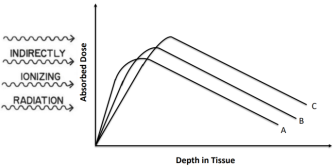

The sequence increasing incident $\gamma \;$energy should be-

C) A, B, C

############### ############### ############### ###############

## HW08-4

### (a)

We can use the following equation, to calculate initial conc. of Co-60


$$C_i =C_f \frac{f+F\;}{f}$$


C_f = 3e-5;         % monthly avg. conc' of Co-60; uCi/ml
f = 4e3;            % monthly liq' waste volm; l
F = 1e6;            % monthly sewer discharge; l

C_i = C_f *(f + F)/f  % initial conc. of Co-60; uCi/ml

C_i = 0.0075

(Ans)

### (b)

Here, we have-

a = 1*1e6;          % Co-60 activity; mCi
V = 4e4*1e3;        % volume, annual; ml
C_f = a/V           % annual avg. conc'; uCi/ml

C_f = 0.0250

Then we get-

fa = 4e4;           % annual liq' waste volm'; l
Fa = 1e6*12;        % annual sewer discharge; 

C_ia = C_f *(fa + Fa)/fa % initial conc., annual; uCi/ml

C_ia = 7.5250

(Ans)

############### ############### ############### ###############

## HW08-5

We know the following equation


$$R_{\textrm{aipj}} =C_{\textrm{ip}} \;U_{\textrm{ap}} \;D_{\textrm{aipj}}$$


    R = dose; C = Conc. of radionuclide; U = usage factor; D = Dose conv. factor

    i = radionuclide species; p = pathway (air/ground); a = annual, j = organ index

We have, for air-

C_a = 1e-11 *1e6;       % conc', air; pCi/ml
Dv_a = 6.12e-6;         % conv' F, air; mrem/pCi
  ml_Cm = 1e6;          % ; ml/m^3
u_a = 3700;             % usage factor, air; m^3/y 
u_a = u_a*ml_Cm;        % ; ml/y

d_a = C_a*Dv_a*u_a      % dose from air; mrem/y

d_a = 0.2264

Then again, for ground intake

C_g = 1e-6 *1e6;        % conc', grnd; pCi/ml
Dv_g = 1.7e-8;          % conv' F, grnd; mrem/pCi
  ml_l = 1e3;           % ; ml/m^3
u_g = 800;              % usage factor, grnd; m^3/y 
u_g = u_g*ml_l;         % ; ml/y

d_g = C_g*Dv_g*u_g      % dose from grnd; mrem/y

d_g = 0.0136

And, for ingestion,

C_i = 1e-8 *1e6;        % conc', ing'; pCi/ml
Dv_i = 1.56e-5;         % conv' F, ing'; mrem/pCi
  ml_l = 1e3;           % ; ml/m^3

  Assuming, kg ~ litre

u_i = (330 +6.9 +520 +330);  % usage factor, ing'; m^3/y 
u_i = u_i*ml_l;         % ; ml/y

d_i = C_i*Dv_i*u_i      % dose from ing'; mrem/y

d_i = 0.1852

Then, we have the CEDE-

CEDE = d_a + d_g + d_i      % CEDE; mrem/y

CEDE = 0.4252

(Ans) 

############### ############### ############### ###############

## HW08-6

Here, the total CEDE is 0.4252*e-3 rem/y. This value is way below the public dose limit of 0.1 rem/y for- as per ALARA. So, my judgement is- the facilitiy's practice is ethical.